# Example 6.26: Neural Network Model for Gibbs Reactor

Note: this script reproduces Example 6.26 (Section 6.7.1) of **Statistics for Chemical Engineers**: a neural network model of the Gibbs reactor conversion. Victor Z UW-Madison, 2020 NN prediction for gibbs data [https://www.mathworks.com/help/deeplearning/gs/fit-data-with-a-neural-network.html#f9-33554](https://www.mathworks.com/help/deeplearning/gs/fit-data-with-a-neural-network.html#f9-33554)

clc; clear all; close all hidden;

## Data

create data set

load ('./Data/gibbs_hightemp_class.dat')
datahigh=gibbs_hightemp_class;
load ('./Data/gibbs_lowtemp_class.dat')
datalow=gibbs_lowtemp_class;
data=[datahigh;datalow];
n=length(data);

rng(0)
inputs=data(:,1:2)'+rand(2,n)*0.1; % temperature and pressure
targets=data(:,3)'+rand(1,n)*0.1;   % yield

## Neural network

construct simple NN The default network for function fitting (or regression) problems, fitnet is a feedforward network with the default tan-sigmoid transfer function in the hidden layer and linear transfer function in the output layer. The network has one output neuron, because there is only one target value associated with each input vector.

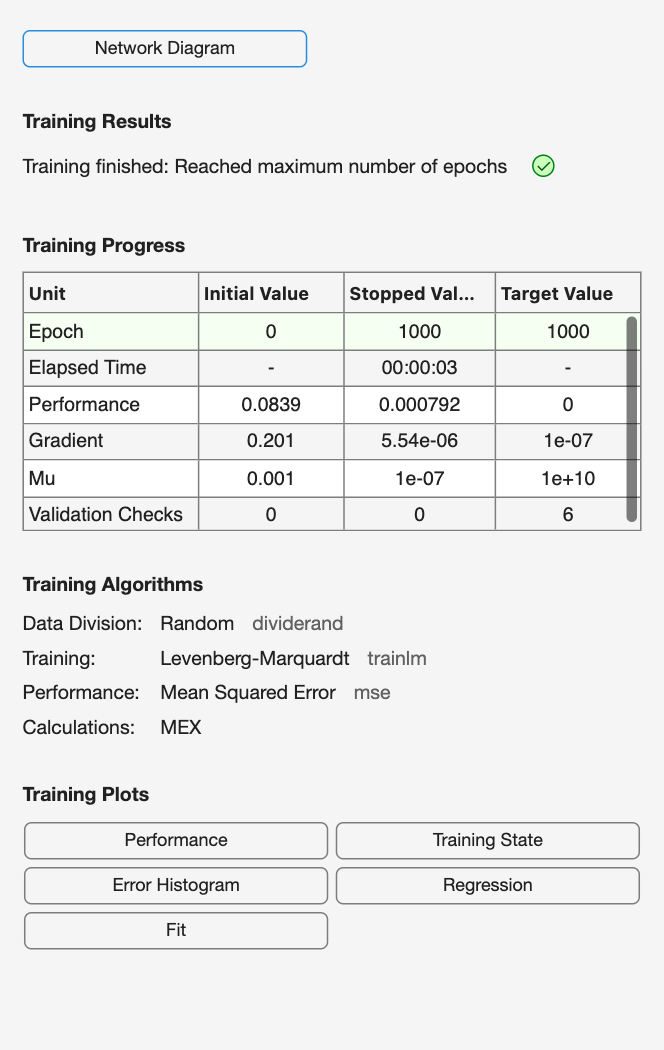

hiddenLayerSize = 2;
net = fitnet(hiddenLayerSize);
net.divideParam.trainRatio = 1.0;
net.divideParam.valRatio = 0;
net.divideParam.testRatio = 0;

[net, tr] = train(net, inputs, targets);

outputs = net(inputs);
errors = gsubtract(targets, outputs);
performance = perform(net, targets, outputs);
eps2=errors;

% compare against gpr
gprMdl = fitrgp(inputs',targets','KernelFunction','squaredexponential')

gprMdl =   RegressionGP
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 500
           KernelFunction: 'SquaredExponential'
        KernelInformation: [1×1 struct]
            BasisFunction: 'Constant'
                     Beta: 0.3441
                    Sigma: 0.0284
        PredictorLocation: []
           PredictorScale: []
                    Alpha: [500×1 double]
         ActiveSetVectors: [500×2 double]
            PredictMethod: 'Exact'
            ActiveSetSize: 500
                FitMethod: 'Exact'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [500×1 logical]
            LogLikelihood: 1.0511e+03
         ActiveSetHistory: []
           BCDInformation: []

  Properties, Methods


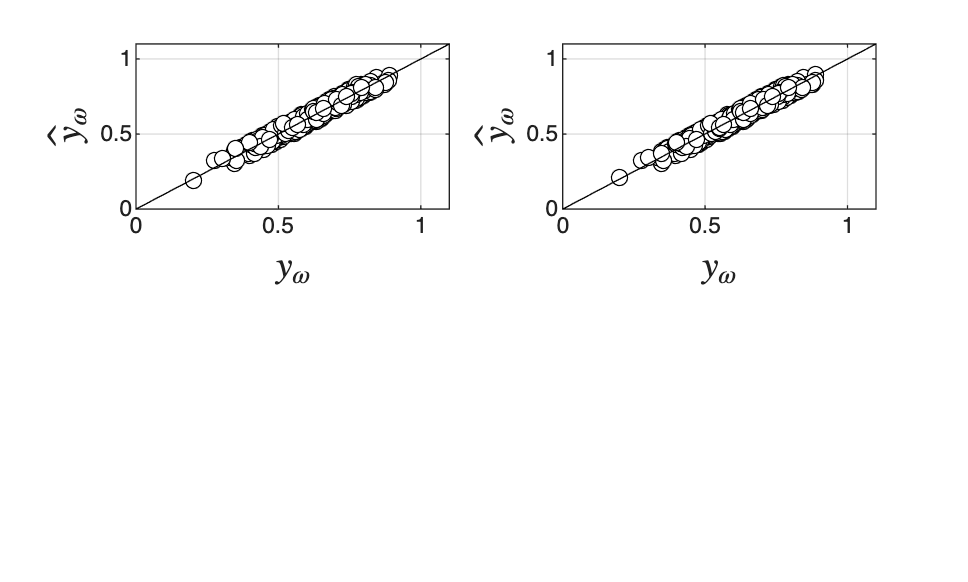

[outputsgpr,outputsd,outputsci] = predict(gprMdl,inputs');
eps=targets'-outputsgpr;

% plot fit
figure(1)
subplot(2,2,1)
xx=linspace(0,1.1);
plot(targets,outputsgpr,'blacko','MarkerFaceColor','w')
grid on
hold on
plot(xx,xx,'black-');
xlabel('$y_\omega$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}_\omega$','Interpreter','latex','FontSize',14)
axis([0,1.1,0,1.1])

subplot(2,2,2)
plot(targets,outputs,'blacko','MarkerFaceColor','w')
hold on
grid on
plot(xx,xx,'black-')
xlabel('$y_\omega$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}_\omega$','Interpreter','latex','FontSize',14)
axis([0,1.1,0,1.1])
print -depsc ch6_benchmark_gibbs_kriging_NN.eps

## Note

As in the book, a network with one layer and a few perceptrons fits this highly nonlinear model extremely well.